# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to Sunday 22th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the determinant of the resulting rotation matrix 

matrix = Eaa2rotMat([2; 1; 3], 20);
determinant = det(matrix)

determinant = 1

- Compare the transpose and the inverse of the resulting matrix

matrix'

ans =     0.9569    0.2828   -0.0656
   -0.2656    0.9440    0.1957
    0.1173   -0.1699    0.9785


inverse = inv(matrix)

inverse =     0.9569    0.2828   -0.0656
   -0.2656    0.9440    0.1957
    0.1173   -0.1699    0.9785


new_matrix = matrix' - inv(matrix)

new_matrix = 	1.0e+-15 *

    0.2220    0.0555   -0.0416
         0         0         0
         0         0         0


- Using the output matrix, transform a vector parallel to the axis of rotation. 

vector = [-4; -2; -6];
vector_transformed = matrix * vector

vector_transformed =    -4.0000
   -2.0000
   -6.0000


What happens?

    *The transformed vector is the same as the initial vector. This is because the vector being parallel to the axis rotates around itself, therefore the coordinates do not change.*

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the escalar product between the original  vector and the transformed one.

vector2 = [6; 6; 6];
vector3 = cross(vector, vector2)

vector3 =     24
   -12
   -12


vector3_transformed = matrix * vector3

vector3_transformed =    24.7464
   -2.5011
  -15.6639


dot_product = dot(vector3, vector3_transformed)

dot_product = 811.8944

vector3_module = sqrt(vector3' * vector3);
cosd(20)

ans = 0.9397

dot_product / vector3_module^2

ans = 0.9397

 What you observe?

*    Thanks to the dot product formula you can find the angle which rotated the vector without inverse mapping the rotation matrix.*

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5)

axisM =     0.3507    0.1967    0.3790    0.3654    0.0277   -0.2722    0.0747    0.0860   -0.4165    0.2298    0.2690    0.0801    0.3627   -0.2906   -0.4680   -0.4505   -0.3769   -0.3109   -0.2181   -0.0009   -0.3761    0.3739    0.0650   -0.2940   -0.3943    0.1210    0.4312   -0.4366    0.4844    0.0134   -0.3661   -0.1987   -0.0329    0.3422   -0.1521   -0.3229    0.3985    0.0400   -0.2122    0.2640   -0.3219    0.0219   -0.2911   -0.0315    0.2455   -0.3158   -0.3659   -0.4285   -0.0583   -0.3033
    0.0606    0.0828    0.4889    0.1126   -0.0205   -0.0019    0.3452   -0.2533    0.1260    0.3908    0.0814   -0.4830   -0.0157    0.0523    0.1147   -0.0104   -0.2945   -0.4573    0.0386    0.0358   -0.0096   -0.2297    0.1403    0.4479   -0.3580    0.0737    0.2287    0.3604    0.3589   -0.3224   -0.4691   -0.2045    0.1482    0.0590   -0.0540    0.1628   -0.3818    0.2069   -0.0855    0.3182   -0.1404   -0.1642    0.4052    0.4121    0.2363    0.0972   -0.2874   -0.2575   -0.4867 

 contains 100 random (non-unit) axis. While 

theta = linspace(0,6*pi,100)

theta =          0    0.1904    0.3808    0.5712    0.7616    0.9520    1.1424    1.3328    1.5232    1.7136    1.9040    2.0944    2.2848    2.4752    2.6656    2.8560    3.0464    3.2368    3.4272    3.6176    3.8080    3.9984    4.1888    4.3792    4.5696    4.7600    4.9504    5.1408    5.3312    5.5216    5.7120    5.9024    6.0928    6.2832    6.4736    6.6640    6.8544    7.0448    7.2352    7.4256    7.6160    7.8064    7.9968    8.1872    8.3776    8.5680    8.7584    8.9488    9.1392    9.3296


 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair theta-axis, (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

trace_vector = zeros(1, 100)

trace_vector =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:1:100
    aux_vector = [axisM(1,  i); axisM(2, i); axisM(3, i)];
    aux_matrix = Eaa2rotMat(aux_vector, theta(i));
    trace_vector(i) = trace(aux_matrix);
end

trace_vector

trace_vector =     3.0000    3.0000    3.0000    2.9999    2.9998    2.9997    2.9996    2.9995    2.9993    2.9991    2.9989    2.9987    2.9984    2.9981    2.9978    2.9975    2.9972    2.9968    2.9964    2.9960    2.9956    2.9951    2.9947    2.9942    2.9936    2.9931    2.9925    2.9920    2.9913    2.9907    2.9901    2.9894    2.9887    2.9880    2.9872    2.9865    2.9857    2.9849    2.9841    2.9832    2.9824    2.9815    2.9806    2.9796    2.9787    2.9777    2.9767    2.9757    2.9746    2.9735


- Make a plot of the trace that you have obtained vs the theta angle. Explain what you observe.

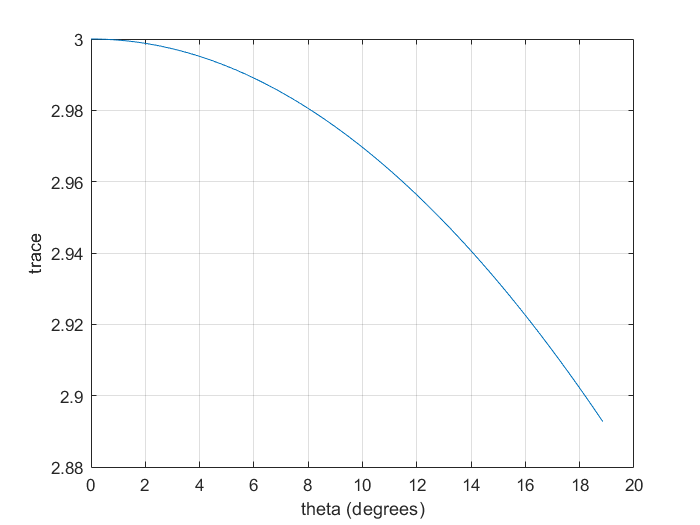

plot(theta, trace_vector)
xlabel('theta (degrees)')
ylabel('trace')
grid on

               * Explanation Here: First of all, we can observe that the bigger the angle, the smaller the trace. This is due to the following formula:*

*φ = arccos((trace (R) − 1) / 2)   which is:*

*cos(φ) = (trace (R) − 1) / 2*

*Therefore, the bigger the angle the lower the cosinus of the angle is. And this also makes the trace itself be lower.*

## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

matrix2 = Eaa2rotMat([0.5345; 0.2673; 0.8018], 20);
[euler_axis, euler_angle] = rotMat2Eaa(matrix2)

euler_axis =     0.5345
    0.2673
    0.8018


euler_angle = 20.0000

- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


*            Comment here and include code if you need it.*

[euler_axis_r1, euler_angle_r1] = rotMat2Eaa([1 0 0; 0 1 0; 0 0 1])

euler_axis_r1 =     0.5774
    0.5774
    0.5774


euler_angle_r1 = 0

[euler_axis_r2, euler_angle_r2] = rotMat2Eaa([-1/3 2/3 2/3; 2/3 -1/3 2/3; 2/3 2/3 -1/3])

euler_axis_r2 =     0.3333
    0.3333
    0.3333


euler_angle_r2 = 180

[euler_axis_r3, euler_angle_r3] = rotMat2Eaa([0 0 -1; 0 -1 0; -1 0 0])

euler_axis_r3 =     0.5000
         0
    0.5000


euler_angle_r3 = 180

*What they have in common? The sinus of their Euler principal angle is 0. *

*Then, when we use the formula to get the Euler principal axis, we have to divide by 2 * 0, which is 0. Thus, giving us infinite values for the skew-symmetric matrix, which is where we get the Euler principal axis.*

*If the rotation angle is 0 degrees, there is an infinite number of axis. Also, if the rotation angle is 180 degrees, there are two possible axis because we can only use the symmetrical matrices of the Rodriguez formula.*

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

*Solution here : We implemented the solution inside the rotMat2Eaa.m function itself. Note that in case the angle is zero, there are many possible axis, meanwhile, if the angle is 180 there are two possible axis and we only provide one of those.*

[euler_axis_r2, euler_angle_r2] = rotMat2Eaa([-1/3 2/3 2/3; 2/3 -1/3 2/3; 2/3 2/3 -1/3])

euler_axis_r2 =     0.3333
    0.3333
    0.3333


euler_angle_r2 = 180

New_Mat = Eaa2rotMat([0.3333; 0.3333; 0.3333], 180)

New_Mat =    -0.3333    0.6667    0.6667
    0.6667   -0.3333    0.6667
    0.6667    0.6667   -0.3333


## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ ( , , )$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ ( , , )$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ ( , , )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8


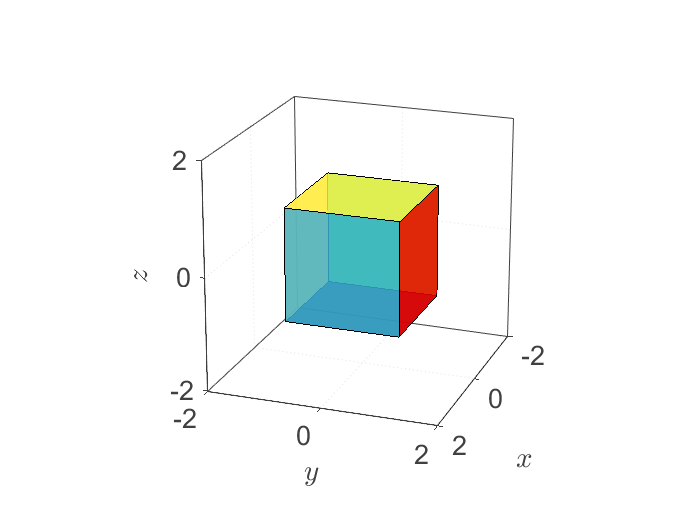

R = eye(3);
R1 = Eaa2rotMat([0; 1; 0], 90);
R2 = Eaa2rotMat([1; 0; 0], 90) * Eaa2rotMat([0; 1; 0], 90);
R3 = Eaa2rotMat([0; 0; 1], -90) * Eaa2rotMat([1; 0; 0], 180);

M_mod = (R*M')';
M_mod1 = (R1*M')';
M_mod2 = (R2*M')';
M_mod3 = (R3*M')';
Cubeplot(M_mod);

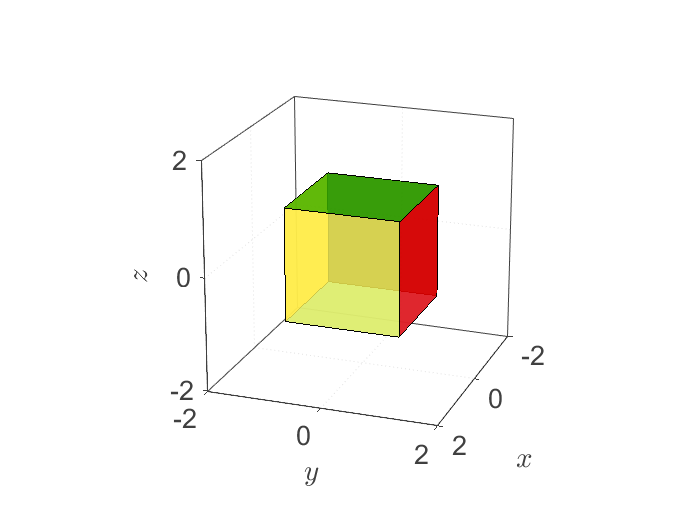

Cubeplot(M_mod1);

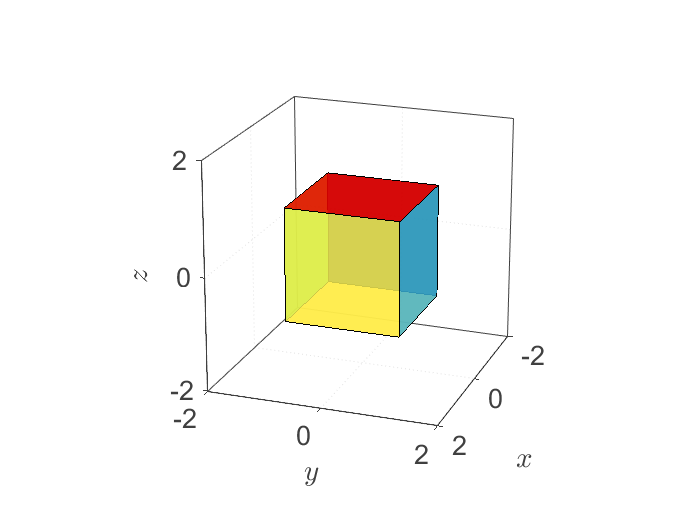

Cubeplot(M_mod2);

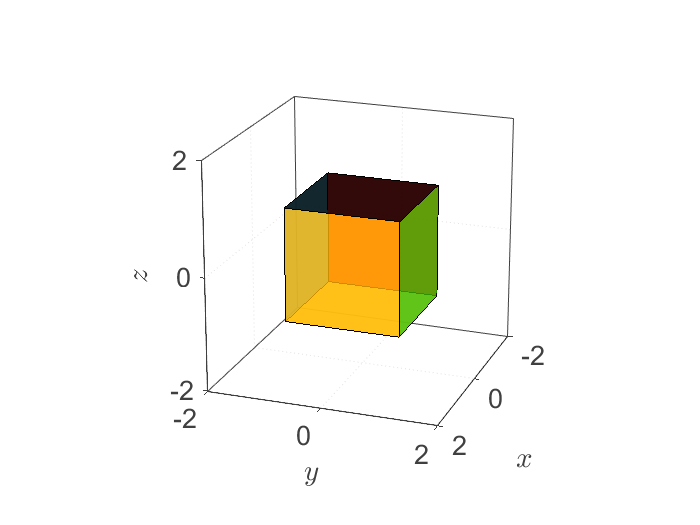

Cubeplot(M_mod3);

## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

- Calculate the determinant of the resulting rotation matrix 

matrix3 = eAngles2rotM(25, -30, 60)

matrix3 =     0.4330   -0.8905    0.1394
    0.7500    0.2702   -0.6038
    0.5000    0.3660    0.7849


matrix3_det = det(matrix3)

matrix3_det = 1.0000

- Compare the transpose and the inverse of the resulting matrix

matrix3_transpose = matrix3'

matrix3_transpose =     0.4330    0.7500    0.5000
   -0.8905    0.2702    0.3660
    0.1394   -0.6038    0.7849


matrix3_inverse = inv(matrix3)

matrix3_inverse =     0.4330    0.7500    0.5000
   -0.8905    0.2702    0.3660
    0.1394   -0.6038    0.7849


*As we can see, both transpose and inverse matrices are the same, because a rotation matrix is orthonormal.*

**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented. You can set phi = 0 if you need it.

[angle1, angle2, angle3] = rotM2eAngles(matrix3)

angle1 = 25.0000

angle2 = 30.0000

angle3 = 60.0000

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.

matrix4 = eAngles2rotM(90, 45, 90)

matrix4 =          0         0    1.0000
    0.7071    0.7071         0
   -0.7071    0.7071         0


[angle1, angle2, angle3] = rotM2eAngles(matrix4)

angle1 = 90

angle2 = -45.0000

angle3 = 90